1) Retrieve and plot system data

% Import data from Excel file
% Home -> Import Data -> Select Data Excel File -> Import Selection
% VVV Change variable below VVV
file_name = data5;

timestamp1 = data1.Timestampms ./ 1000;
duty_cycle1 = data1.DutyCycle;
velocity1 = data1.VelocityRPM;

timestamp2 = data2.Timestampms ./ 1000;
duty_cycle2 = data2.DutyCycle;
velocity2 = data2.VelocityRPM;

timestamp3 = data3.Timestampms ./ 1000;
duty_cycle3 = data3.DutyCycle;
velocity3 = data3.VelocityRPM;

timestamp4 = data4.Timestampms ./ 1000;
duty_cycle4 = data4.DutyCycle;
velocity4 = data4.VelocityRPM;

timestamp5 = data5.Timestampms ./ 1000;
duty_cycle5 = data5.DutyCycle;
velocity5 = data5.VelocityRPM;

timestamp = [];
duty_cycle = [];
velocity = [];
for i = 1:length(timestamp1)
    timestamp = [timestamp median([timestamp1(i) timestamp2(i) timestamp3(i) timestamp4(i) timestamp5(i)])];
    duty_cycle = [duty_cycle median([duty_cycle1(i) duty_cycle2(i) duty_cycle3(i) duty_cycle4(i) duty_cycle5(i)])];
    velocity = [velocity median([velocity1(i) velocity2(i) velocity3(i) velocity4(i) velocity5(i)])];
end

2) Estimate first order system with deadtime

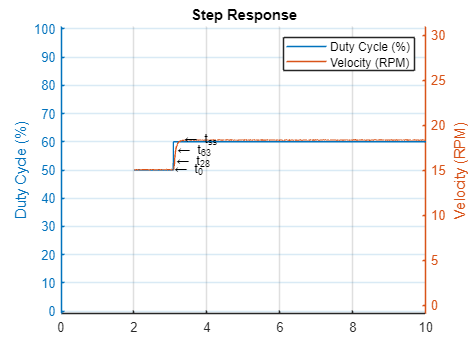

step_index = find(diff(duty_cycle) ~= 0) + 1;

RPM_0 = velocity(step_index);
RPM_SS = median(velocity) * 0.9975;
RPM_28 = (RPM_SS - RPM_0) * 0.28 + RPM_0;
RPM_63 = (RPM_SS - RPM_0) * 0.632 + RPM_0;

% Removes duplicate velocities from array
% (Allows interpolation)
map = false(size(velocity));
for i = 1:length(velocity)
    if any(velocity(1:i-1) == velocity(i))
        map(i) = true;
    end
end
timestamp = timestamp(~map);
duty_cycle = duty_cycle(~map);
velocity = velocity(~map);

step_index = find(diff(duty_cycle) ~= 0) + 1;

t_0 = timestamp(step_index);
t_SS = interp1(velocity, timestamp, RPM_SS, 'linear');
t_28 = interp1(velocity, timestamp, RPM_28, 'linear');
t_63 = interp1(velocity, timestamp, RPM_63, 'linear');

hold on
yyaxis left;
plot(timestamp, duty_cycle .* 100)
ylabel('Duty Cycle (%)');
ylim([-1, 101])

yyaxis right;
plot(timestamp, velocity)
ylabel('Velocity (RPM)')
text(t_0, RPM_0, '\leftarrow t_0')
text(t_28, RPM_28, '\leftarrow t_2_8')
text(t_63, RPM_63, '\leftarrow t_6_3')
text(t_SS, RPM_SS, '\leftarrow t_s_s')

ylim([-1, 31])

title('Step Response')
legend('Duty Cycle (%)','Velocity (RPM)')
grid on
hold off


K_p = (RPM_SS - RPM_0) / (max(duty_cycle) - min(duty_cycle));
t = 1.49 * (t_63 - t_28);
t_d = t_63 - t - t_0;

K_p = 94.393750

K_p = 94.3937

t = 0.029800

t = 0.0298

t_d = 0.034970

t_d = 0.0350

3) Tune PI controller

num = [K_p];
den = [t 1];
sys = tf(num, den, 'InputDelay', t_d)

sys =
 
                     94.39
  exp(-0.035*s) * ------------
                  0.0298 s + 1
 
Continuous-time transfer function.
Model Properties



C0 = pidstd(1,1,1);
tuner = pidTuner(sys, C0);

C0 = pidstd(1,1,1);
tuner  = pidtune(sys, C0)

tuner =
 
             1      1          
  Kp * (1 + ---- * --- + Td * s)
             Ti     s          

  with Kp = 0.00571, Ti = 0.0337, Td = 6.09e-06
 
Continuous-time PID controller in standard form
Model Properties
